# **3GPP 38.901 Propagation Model**

## Calculates distance(3D) based on the propagation model of **3GPP TR 38.901 version 17.0.0 Release 17**.

- Only UMa and UMi Senarios.

- Frequency Range : 0.5 to 100 GHz.

### Inputs:

- Senario ["UMa","UMi"].

- Line Of Sight or Non Line Of Sight  ["LOS","NLOS"].

- Path Loss (dB).

- Frequency (GHz).

- Base Station Height (m).

- User Terminal Height (m).

### Output:

- Distance (m).

function d = TR_3GPP_38901(Senario,LOS_NLOS,PL,f,h_BS,h_UT)
switch (Senario)
    case "UMa"
        %Calculating distance for UMa LOS Senario
        d_BP=4*(h_BS-1)*(h_UT-1)*(f*1e9/physconst("LightSpeed"));
        d_3D=10^((PL-28-20*log10(f))/22);
        d_2D=sqrt(d_3D^2-(h_BS-h_UT)^2);
        if d_2D>d_BP
            d_3D=10^((PL-28-20*log10(f)+9*log10(d_BP^2+(h_BS-h_UT)^2))/40);
        end
        d_UMa_LOS=d_3D;
        %Calculating distance for UMa NLOS Senario
        d_3D=10^((PL-13.54-20*log10(f)+0.6*(h_UT-1.5))/39.08);
        d_UMa_NLOS=d_3D;
        
        switch (LOS_NLOS)
            case "LOS"
                d=d_UMa_LOS;
            case "NLOS"
                d=d_UMa_NLOS;           
        end
        
    case "UMi"
        %Calculating distance for UMi LOS Senario
        d_BP=4*(h_BS-1)*(h_UT-1)*(f*1e9/physconst("LightSpeed"));
        d_3D=10^((PL-32.4-20*log10(f))/21);
        d_2D=sqrt(d_3D^2-(h_BS-h_UT)^2);
        if d_2D>d_BP
            d_3D=10^((PL-32.4-20*log10(f)+9.5*log10(d_BP^2+(h_BS-h_UT)^2))/40);
        end
        d_UMi_LOS=d_3D;
        %Calculating distance for UMi NLOS Senario
        d_3D=10^((PL-22.4-21.3*log10(f)+0.3*(h_UT-1.5))/35.3);
        d_UMi_NLOS=d_3D;
        
        switch (LOS_NLOS)
            case "LOS"
                d=d_UMi_LOS;
            case "NLOS"
                d=d_UMi_NLOS;           
        end
          
end
end

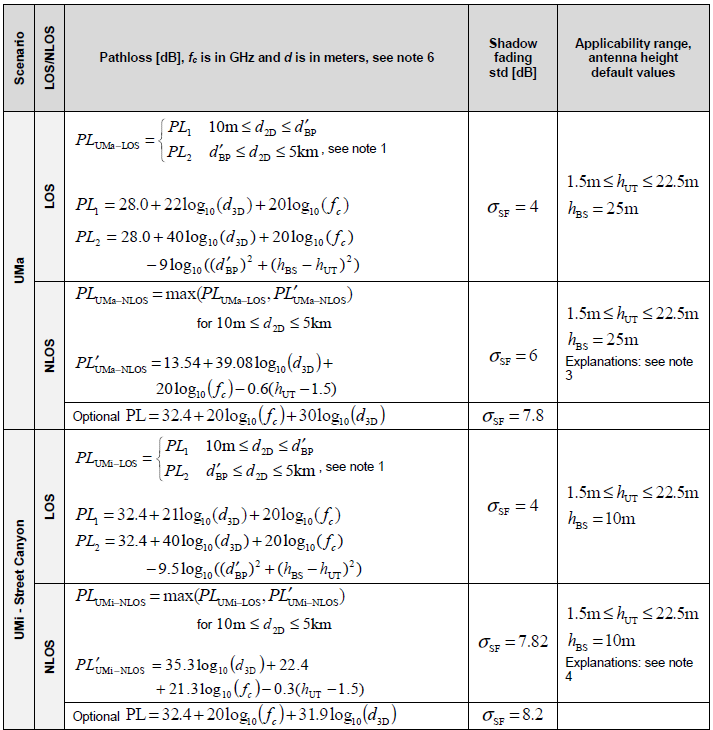

## **References:**

- **3GPP TR 38.901 version 17.0.0 Release 17**.

- **Atoll User Manual Radio.**

- **Atoll Technical Reference Guide Radio.**